% Autor: Asiye Örs (OEAS93), Arslan Gamze (ARGA43), Muhammed Shamil (SHMU26)
% Datum: 17.11.2024

% ZL = Zyklus links
% ZR = Zyklus rechts
% KL = Knie links
% KR = Knie rechts
% 120 = steht für die Messungen mit einem vorgegebenem Takt von 120bpm

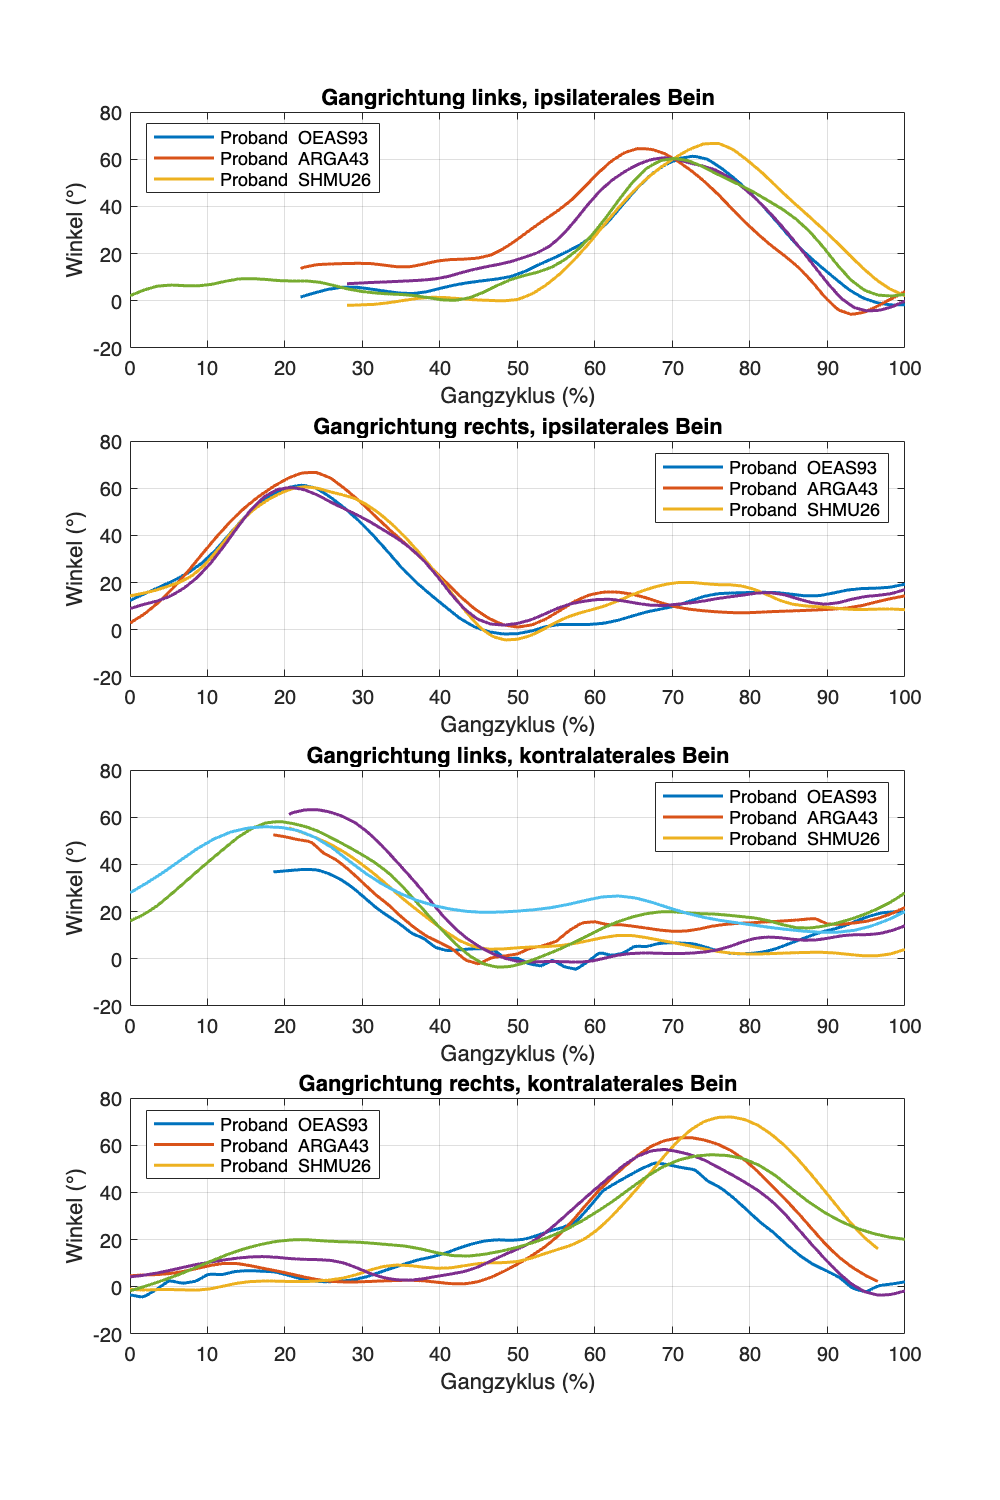

clear all; close all; clc; warning('off')
S1 = {'OEAS93','ARGA43','SHMU26'};     % Autoren
S2 = {'KL','KR'};                      % Knie links, Knie Rechts  
S3 = {'ZL','ZR'};                      % Zyklus links, Zyklus Rechts 
% Konstruiere die Variablennamen, importiere die Daten und speichere
% die Daten in die richtigen Variablen.
for k1 = 1 : length(S1)
    for k2 = 1 : length(S2)
        for  k3 = 1 : length(S3)
            myfilename1 = sprintf('%s_%s_%s.txt', S1{k1}, S2{k2}, S3{k3});
            myfilename2 = sprintf('%s_%s_%s_120.txt', S1{k1}, S2{k2}, S3{k3});
            eval([S1{k1} '_' S2{k2} '_' S3{k3} '= [ readmatrix(myfilename1)];']);
            eval([S1{k1} '_' S2{k2} '_' S3{k3} '_120' '= [readmatrix(myfilename2)];']);
        end
    end
end
%
%gcf = figure();
fig1 = figure('Position', [50, 50, 500, 750]);
titel1 = {'links','rechts'};
titel2 = {'ipsilaterales','kontralaterales'};
for k3 = 1 : length(S3) 
    for k2 = 1 : length(S2)
        if k3 == 1 
            subplot(4, 1, k2)
        else 
            subplot(4, 1, k2 + k3)
        end
        for k1 = 1 : length(S1)
            hold on; box on
                             % Konstruiere den Variablennamen für die Daten
            varName = sprintf('%s_%s_%s', S1{k1}, S2{k3}, S3{k2});
            data = eval(varName);  % Extrahiere die Daten aus der Variablen
            plot(data(:,1), data(:,2:end),'LineWidth',1.5) % Plot
        end
        hold off
                                        % to justfiy the titel of the plot
        s = sprintf('Gangrichtung %s, %s Bein', titel1{k2}, titel2{k3});
        title(s);
         % to justfiy the location of the Legend for the second and third
         % subplot to right, otherwise to left
        if ~mod(k2+k3,2)
            legend('Proband  OEAS93','Proband  ARGA43','Proband  SHMU26',...
                                                     'Location','northwest')  
        else
            legend('Proband  OEAS93','Proband  ARGA43','Proband  SHMU26',...
                                                     'Location','northeast')  
        end
        xlabel("Gangzyklus (%)")
        ylabel("Winkel (°)")
        grid on
    end
end

savefig(fig1,'Abbildung1.fig')  % speicher die Abildung als fig Datei

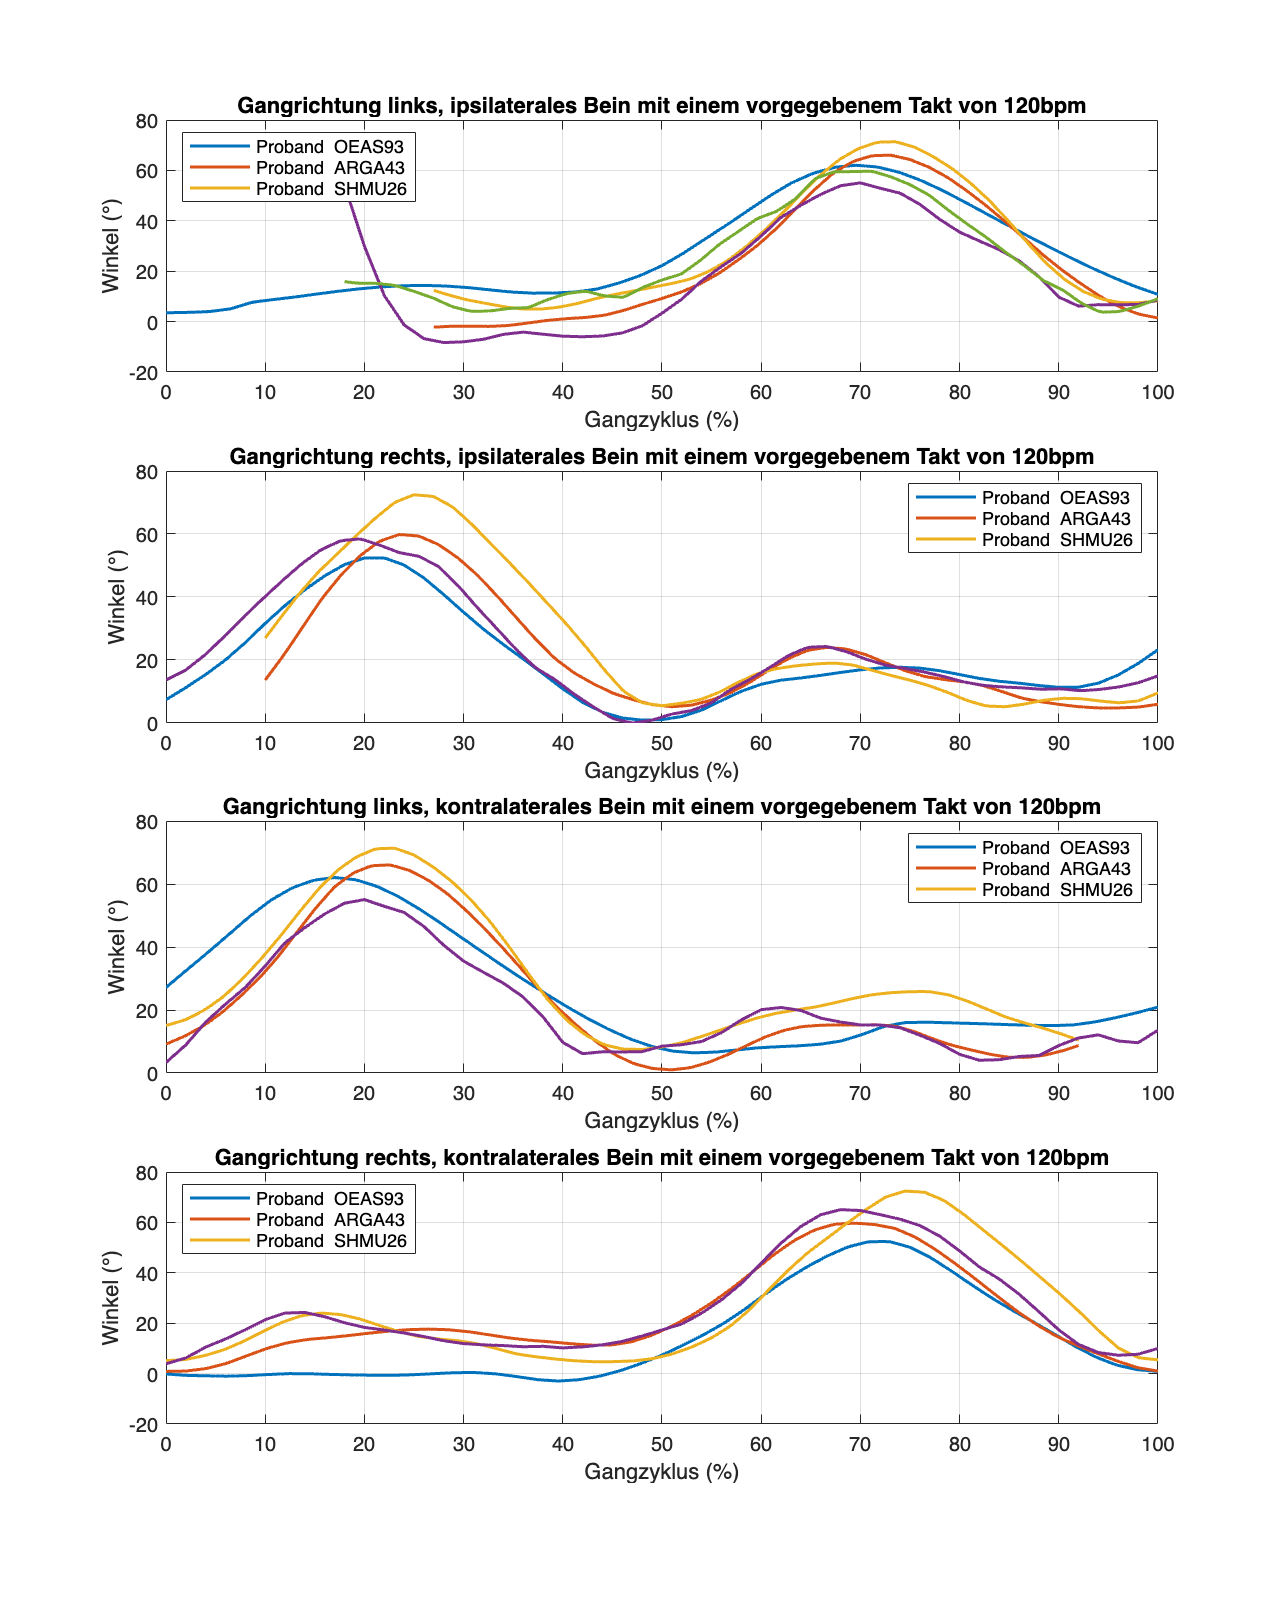

% Plot  die Daten, wenn die Messungen mit einem vorgegebenem Takt von 120bpm

fig2 = figure('Position', [50, 50, 800, 1000]);
for k3 = 1 : length(S3) 
    for k2 = 1 : length(S2)
        if k3 == 1 
            subplot(4, 1, k2)
        else 
            subplot(4, 1, k2 + k3)
        end
        for k1 = 1 : length(S1)
            hold on; box on
            % Konstruiere den Variablennamen für die Daten
            varName = sprintf('%s_%s_%s_120', S1{k1}, S2{k2}, S3{k3});
            data = eval(varName);  % Extrahiere die Daten aus der Variablen
            plot(data(:,1), data(:,2:end),'LineWidth',1.5) % Plot
        end
        hold off
        % to justfiy the titel of the plot
        s = sprintf(['Gangrichtung %s, %s Bein mit einem vorgegebenem '...
                              'Takt von 120bpm'], titel1{k2}, titel2{k3});
        title(s);
        % to justfiy the location of the Legend for the second and third
        % subplot to right, otherwise to left
        if ~mod(k2+k3,2)
            legend('Proband  OEAS93','Proband  ARGA43','Proband  SHMU26',...
                                                     'Location','northwest')  
        else
            legend('Proband  OEAS93','Proband  ARGA43','Proband  SHMU26',...
                                                     'Location','northeast')  
        end
        xlabel("Gangzyklus (%)")
        ylabel("Winkel (°)")
        grid on
    end
end

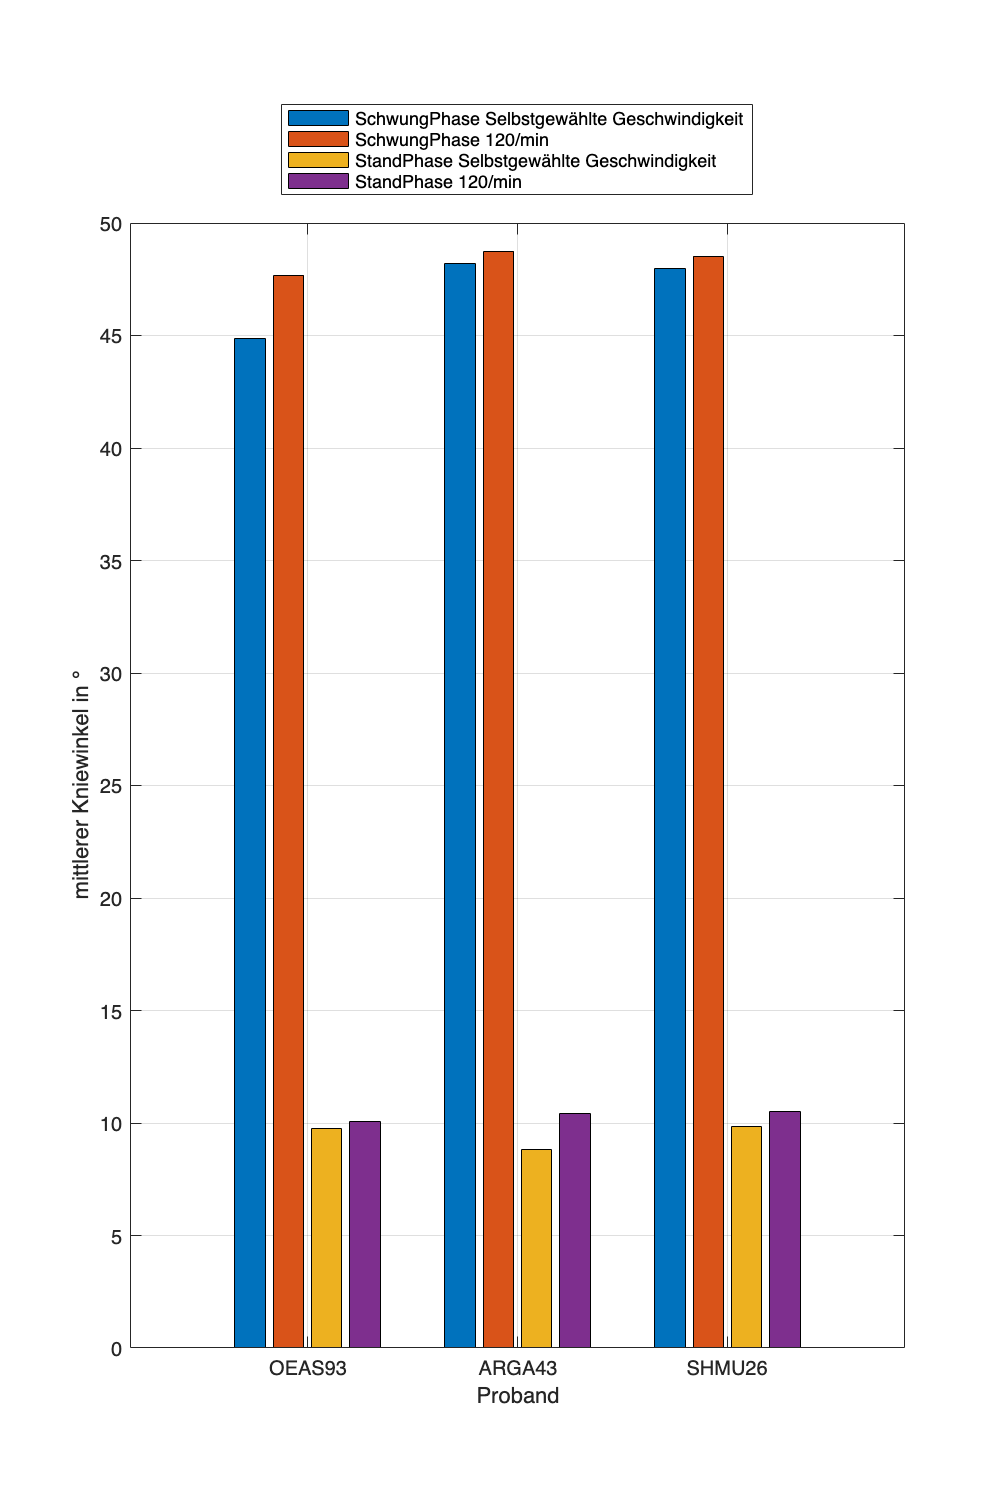

savefig(fig2,'Abbildung2.fig')  % speicher die Abildung als fig Datei
schwung_phase_mitt_alle = []; stand_phase_mitt_alle = [];
for k0 = 1 : 2
    for k1 = 1 : length(S1)
        for k3 = 1 : length(S3)
            for  k2 = 1 : length(S2)
                if k0 == 1
                    varName1 = sprintf('%s_%s_%s',S1{k1},S2{k2},S3{k3});
                else
                    varName1 = sprintf('%s_%s_%s_120',S1{k1},S2{k2},S3{k3});
                end
                data1 = eval(varName1);  % Extrahiere die Daten aus der Variablen
                l1 = 0; schwung_phase = 0.0;
                l2 = 0; stand_phase = 0.0;
                schwung_phase_mitt = [];
                stand_phase_mitt = [];
                for k4 = 2 : size(data1, 2)
                    for k5 =  1 : size(data1, 1)
                        if data1(k5,k4) >= 30              %  40% von 80°
                            schwung_phase = schwung_phase + data1(k5,k4);
                            l1 = l1 +1;
                        else
                            stand_phase = stand_phase + data1(k5,k4);
                            l2 = l2 +1;
                        end                       
                    end
                    ind1 = length(schwung_phase_mitt) + 1;
                    ind2 = length(stand_phase_mitt) + 1;
                    schwung_phase_mitt(ind1) =  schwung_phase /l1;
                    stand_phase_mitt(ind2)   =  stand_phase /l2;
                end
                schwung_phase_mitt_alle = [schwung_phase_mitt_alle schwung_phase_mitt];
                stand_phase_mitt_alle   = [stand_phase_mitt_alle   stand_phase_mitt];
            end
        end
        SchwungPhaseMitt(k0,k1) = mean(schwung_phase_mitt_alle);
        StandPhaseMitt(k0,k1) = mean(stand_phase_mitt_alle);
    end
end
Y = [SchwungPhaseMitt(:,1)' StandPhaseMitt(:,1)'; SchwungPhaseMitt(:,2)'...
     StandPhaseMitt(:,2)'; SchwungPhaseMitt(:,3)' StandPhaseMitt(:,3)' ];
fig3 = figure('Position', [50, 50,500, 750]);

bar(S1, Y)
ylabel('mittlerer Kniewinkel in °')
xlabel('Proband')
legend({'SchwungPhase Selbstgewählte Geschwindigkeit','SchwungPhase 120/min',...
        'StandPhase Selbstgewählte Geschwindigkeit','StandPhase 120/min'},...
        "Location", "northoutside")
grid on

savefig(fig3,'Abbildung3.fig')  % speicher die Abildung als fig Datei